# Low-rank analysis script

% Rex Fung
% Created June 17th, 2024
% Last edited June 17th, 2024


## Experimental parameters

fn = '/mnt/storage/rexfung/20240604epi/3d/eyelevel.h5';
fov = [200, 200, 3]*1e-3;
Nx = 200; Ny = Nx; Nz = 3;
Nsegments = 4;
Nframes = 120;
Ncoils = 32;

## Load data and rearrange to a (k,t,coil) 3D tensor

ksp_raw = read_archive(fn);

Reading ScanArchive header from '/mnt/storage/rexfung/20240604epi/3d/eyelevel.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=600  frame_size=244  nphases=1  nechoes=1  nslices=121  nreceivers=32
data size = 4534.89 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240604epi/3d/eyelevel.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49   50   51   52   53   54   55   56   57   58   59   60   61   62   63   64   65   66   67   68   69   70   71   72   73   74   75   76   77   78   79   80   81   82   83   84   85   86   87   88   89   90   91   92   93   94   95   96   97   98   99  100  

ksp_raw = permute(squeeze(ksp_raw),[2 4 1 3]);
ksp_raw = ksp_raw(:,:,(size(ksp_raw,3) + 1):end); % discard leading empty data

ksp_rampsamp = flip(ksp_raw, 1); % tv6 flips data along FID direction
[Nfid,Ncoils,N] = size(ksp_rampsamp);
ksp_rampsamp = ksp_rampsamp(:,:,1:Ny*Nz*Nframes);
ksp_rampsamp = reshape(ksp_rampsamp,Nfid,Ncoils,Ny,Nz,Nframes);
ksp_rampsamp = permute(ksp_rampsamp, [1 3 4 5 2]); % [Nfid Ny Nz Nframes Ncoils]

% Rearrange segments/shots into proper locations
ksp_rampsamp_reordered = zeros(size(ksp_rampsamp));
for seg = 1:Nsegments
    range = (1:Ny/Nsegments) + (seg-1)*Ny/Nsegments;

    tmp = ksp_rampsamp(:,range,:,:,:);
    tmp(:,1:2:end,:,:,:) = flip(tmp(:,1:2:end,:,:,:),1);
    ksp_rampsamp_reordered(:,seg:Nsegments:end,:,:,:) = tmp;
end
ksp_rampsamp = ksp_rampsamp_reordered;
clear tmp ksp_rampsamp_reordered;

% Construct (k,t x coil) tensor
k_t_c = reshape(ksp_rampsamp,Nfid*Ny*Nz,Nframes,Ncoils);

% demean to avoid dominance of first singular value
k_t_c = k_t_c - mean(k_t_c,2);

## Analyze "rank" with SVD

[U,S,V] = pagesvd(k_t_c,'econ');

% Extract singular values and stable rank
K = min(size(k_t_c,1,2));
SVs_normalized = zeros(K,Ncoils);
stable_ranks = zeros(Ncoils,1);
for coil = 1:Ncoils
    SVs = diag(S(:,:,coil));
    SVs_normalized(:,coil) = SVs./sum(SVs);

    stable_ranks(coil) = sum(SVs.^2)./(SVs(1).^2);
end
clear SVs;

## Visualize

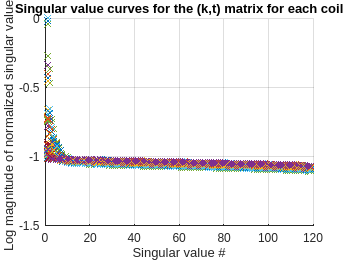

% Scatter plot of singular values for the (k,t) matrix for each coil
figure; scatter(1:K,log(SVs_normalized./max(SVs_normalized(:))),'x'); grid on;
title('Singular value curves for the (k,t) matrix for each coil')
xlabel('Singular value #'); ylabel('Log magnitude of normalized singular values');
ylim([-1.5 0]);

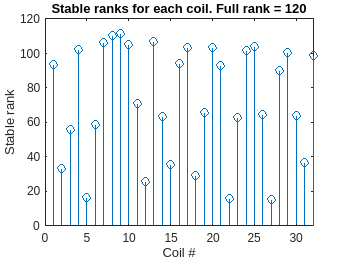


% Stem plot of stable ranks of the (k,t) matrix for each coil
figure; stem(1:Ncoils,stable_ranks);
title(sprintf('Stable ranks for each coil. Full rank = %.0f', K));
xlabel('Coil #'); ylabel('Stable rank');

## Do the same thing but combine time and coil dimensions

k_tc = reshape(k_t_c,Nfid*Ny*Nz,Nframes*Ncoils);
K = min(size(k_tc));
[U,S,V] = svd(k_tc,'econ');

SVs = diag(S);
SVs_normalized = SVs./sum(SVs);
stable_rank = sum(SVs.^2)./(SVs(1).^2);


## Visualize

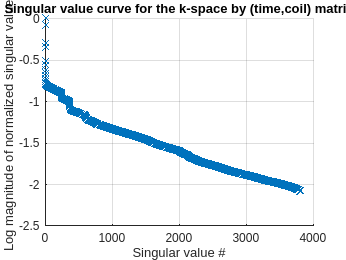

% Scatter plot of singular values for the (k,t x coil) matrix
figure; scatter(1:K,log(SVs./max(SVs)),'x'); grid on;
title('Singular value curve for the k-space by (time,coil) matrix');
xlabel('Singular value #'); ylabel('Log magnitude of normalized singular values');
ylim([-2.5 0]);


fprintf('Stable rank ~= %.0f, Full rank = %.0f',stable_rank,K)

Stable rank ~= 222, Full rank = 3840